# Step Response Modeling

For more information and to download the student courseware please [visit](https://www.quanser.com/resource-type/academic-resources/).

## **Background**

Step response modeling is a simple test based on the step response of a stable system. A step input is given to the system and its response is recorded. The response of a first-order system can be described by the following transfer function:


$$\frac{Y(s)}{U(s)} = \frac{K}{\tau s + 1}$$


where $K
$is the known as the steady-state, or DC gain, and $\tau
$ is the time constant. The step response shown below is generated using this transfer function with $K = 5$ rad/s/V and $\tau = 0.05$ s.

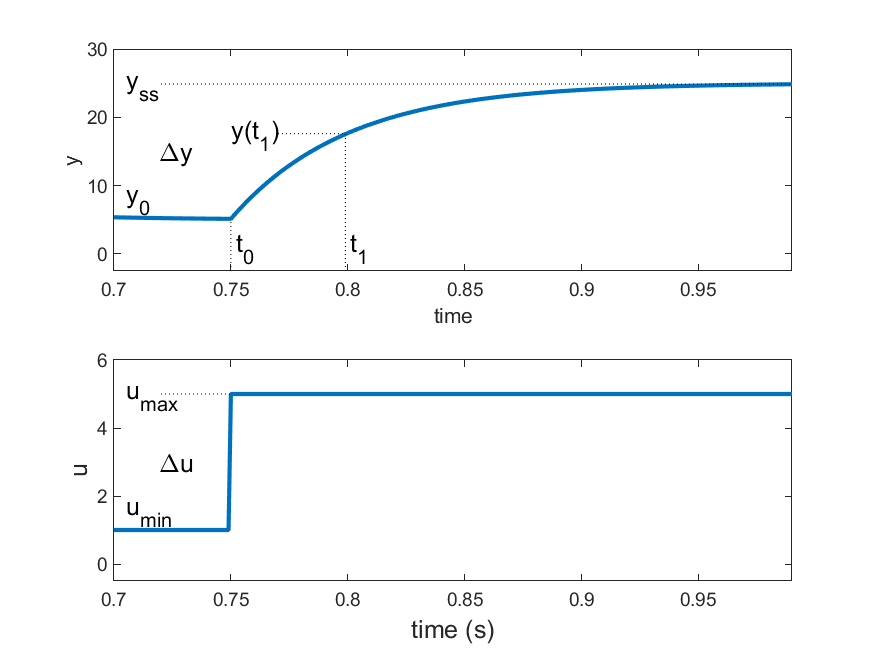

The step input begins at time $t_0
$. The input signal has a minimum value of $u_{min}
$ and a maximum value of $u_{max}
$. The resulting output signal is initially at $y_0
$. Once the step is applied, the output tries to follow it and eventually settles at its steady-state value $y_{ss}
$. The steady-state gain of the system can be found from its response using the input and output signals: 


$$K = \frac{\Delta y}{\Delta u}
$$


where $\Delta y = y_{ss} - y_0$ and $\Delta u = u_{max} -u_{min}$. The time constant of a system, $\tau
$, is defined as the time is takes the output of system to reach $1-e^{-1}=63.2$% of its steady-state value from the initial step time, $t_0$. The point where the output reaches 63.2% of its steady-state value can be defined


$$y(t_1) = 0.632 \Delta y + y_0.$$


where


$$t_1 = t_0 + \tau$$


The time $t_1
$ that corresponds to $y(t_1)$ can be found from the response data shown in the step response figure to obtain the model time constant


$$\tau = t_1 - t_0
$$


### Interactive First-Order Response

Change the steady-state gain, $K$, and the time constant, $\tau$, to see how its affects the step response of a first-order system.

K =10;
tau=0.1;
G = tf( K, [ tau 1 ] )
step(G);
axis([0 2 0 20]); 

## Lab Exercises

The Simulink model shown below applies a 2V step to the motor and reads the servo velocity using the tachometer. 

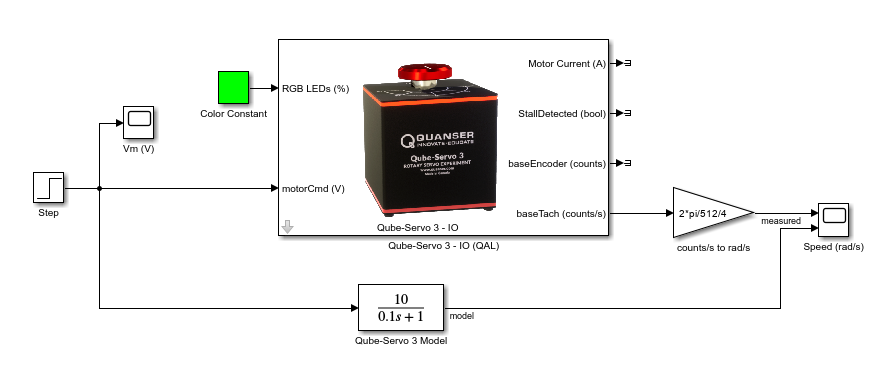

Set the *Simulation stop time* of the Simulink model to apply the step input for a certain duration, e.g. 2.5 s. Using the saved response, the model parameters can then be found as discussed in Background section of this lab. 

### Lab 1: Step Response Model

Follow these steps to find the model of the Qube-Servo 3 experimentally using the step response method:

**Step 1:** Run Quanser Interactive Labs (QLabs) software and open *Qube 3 - DC Motor* | *Servo Workspace*. If you have any issues running the software, please go to the [QLabs support page](https://portal.quanser.com/Support).

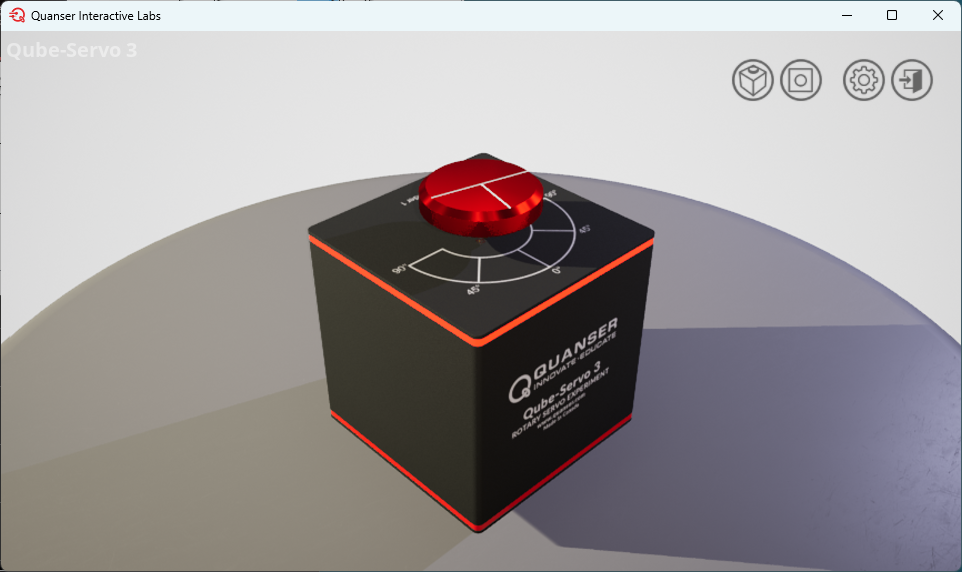

**Step 2:** Open the *q_qube3_step_response *Simulink model shown above.

 q_qube3_step_response; % opens the Simulink mode shown above (if supplied)

**Step 3:** Run the model to apply a 2V step to the virtual servo. The scope response should be similar as shown below.

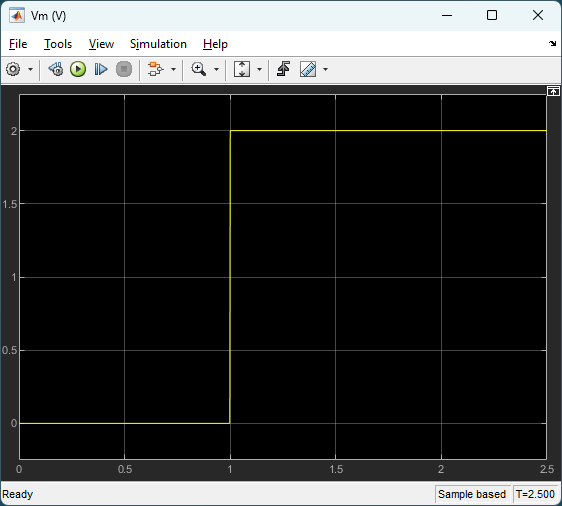 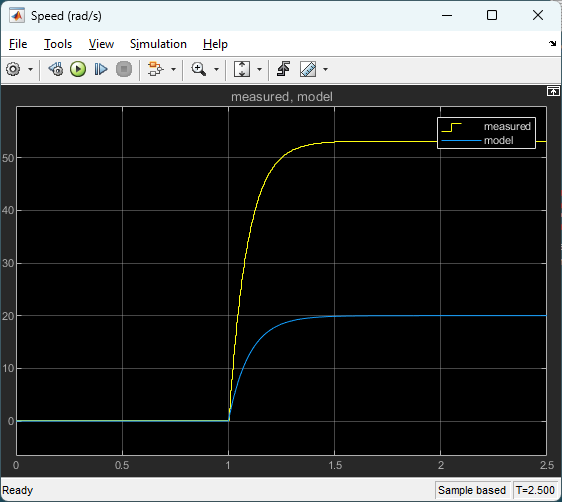 

**Assessment 1: **Plot the response in MATLAB figure. The scopes are configured to save the measured load/disk speed and motor voltage to the MATLAB workspace in the variables `data_wm` and `data_Vm`. The `data_wm.time` is the time vector, `data_wm.signals(1).values` is the measured speed, `data_Vm.time` is the time vector, and `data_Vm.signals` is the applied voltage.

**    Solution: **If the measured data is saved to the variables `data_wm` and `data_Vm`, the following command lines will generate the figure below.

subplot(2,1,1);
plot(data_wm.time,data_wm.signals(1).values);
ylabel('\omega_m (rad/s)');
subplot(2,1,2);
plot(data_vm.time,data_vm.signals.values);
ylabel('V_m (V)');
xlabel('t (s)');	

**Assessment 2**: Find the DC motor steady-state gain, $K$, from the measured step response. Use either the *Cursor Measurements *tool in the Simulink Scope or the *Data Tips *tool in the MATLAB figure to take the measurements.

**    Solution: **Based on the measured step response above, the initial and steady-state load shaft speeds are 0 and 53.2 rad/s and the input voltage amplitude is 2V. Using the steady-state gain equation with this collected data, the resulting steady-state gain is $K = 26.6$ rad/V/s.

**Assessment 3: **Find the time constant, $\tau$, of the Qube-Servo 3 using the measured step response.

**    Solution:** The time of the first decay, $t_1 = t_0 + \tau$, of the measured speed is defined in this equation. Based on the measured step response the time at the shaft speed $\omega_m(t_0 + \tau)=33.6$ rad/s is $t_1 = 1.092$ s, as shown in the MATLAB figure below. Given the step start time is $t_0 = 1.0$ s and the time constant equation, the time constant of the system is $\tau= 0.092$ s. 

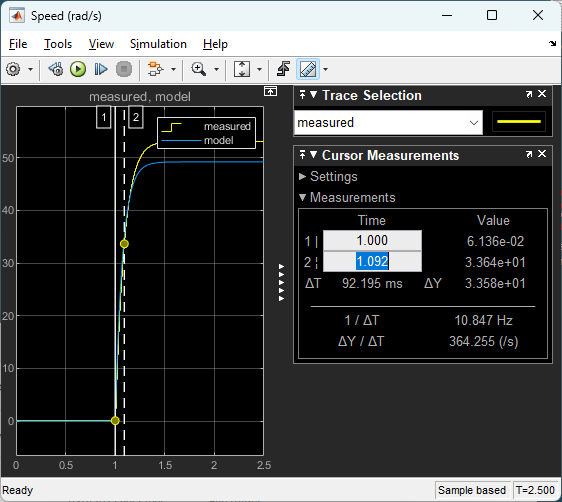

### **Lab 2: Model Validation**

The Simulink model above includes a `Transfer Fcn `block that simulates the first-order model in parallel with the Qube-Servo 3 system (i.e., either the hardware or its virtual twin).

**Assessment 1:  ** To check if your derived model parameters are correct, update *Qube-Servo 3 Model *`Transfer Fcn `block with the $K$and $\tau$ model parameters **that were found**, i.e., not the default values. Run the Simulation

**    Solution: **Modify the Simulink diagram to include a `Transfer Fcn `block using the measured model parameters for the transfer function, e.g., $\frac{26.6}{0.092 s + 1}$, as depicted in the following Simulink diagram.

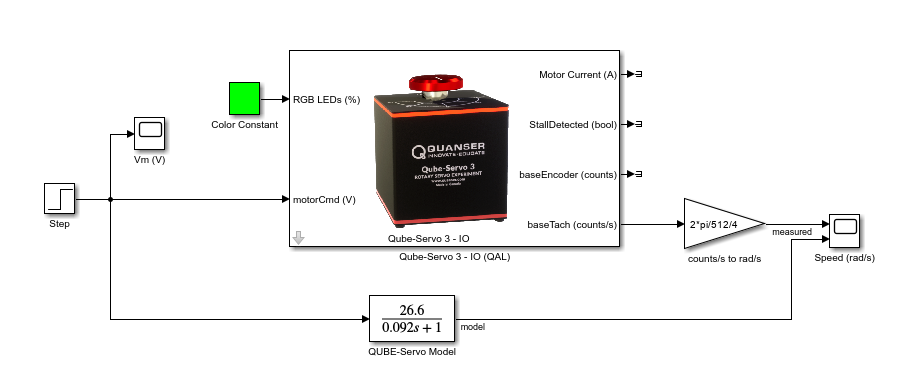

**Assessment 2**: Create a MATLAB figure that displays the measured and simulated speed in one plot and the input voltage in another plot.

**    Solution:** The MATLAB figure shown below displays both the simulated and the measured motor speed from the Simulink model. It can be generated using the following commands:

subplot(2,1,1);
plot(data_wm.time,data_wm.signals(1).values,data_wm.time,data_wm.signals(2).values);
ylabel('\omega_m (rad/s)');
legend('measured','model')
subplot(2,1,2);
plot(data_vm.time,data_vm.signals.values);
ylabel('V_m (V)');
xlabel('t (s)');

**Assessment 3:** Did you derive the model parameters $K$ and $\tau$ correctly? Explain.

**    Solution**:The measured and simulated response match very closely. Given the model represents the actual system accurately, the parameters derived are correct. 

**Step 8**: Stop running the Simulink model. The inertia disk on the Virtual Qube-Servo 3 in QLabs should no longer be spinning and the status LED should now be red.

**Step 9**: Click on the *Exit to Main Menu *button in the top right corner of QLabs to exit the Qube-Servo 3 DC Motor Virtual Experiment workspace.

**Step 10**: Log off QLabs by clicking on the *Logout *button and click on *Exit* to shut down the application.